# Homework 7

Math 3607, Autumn 2021

Marco LoPiccolo

clc

## Problem 1.

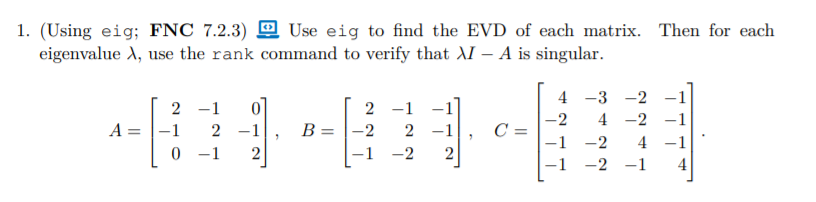

A = [2 -1 0; -1 2 -1; 0 -1 2];
B = [2 -1 -1; -2 2 -1; -1 -2 2];
C = [4 -3 -2 -1; -2 4 -2 -1; -1 -2 4 -1; -1 -2 -1 4];
[V, D] = eig(A)

V =                        0.5        -0.707106781186547                      -0.5
         0.707106781186547      4.88509860010542e-17         0.707106781186547
                       0.5         0.707106781186547                      -0.5


D =          0.585786437626905                         0                         0
                         0                         2                         0
                         0                         0          3.41421356237309


AcheckEVD = norm(A - V*D/V)

AcheckEVD =       4.00296604248672e-16


for i = 1:3
    rank(D(i,i)*eye(3) - A)
end

ans =      2


ans =      2


ans =      2


%rank is less than number of columns therefore the matrix is singular
[S, T] = eig(B)

S =           0.473810655208375 +                     0i          -0.17690989950181 +     0.293139070201401i          -0.17690989950181 -     0.293139070201401i
          0.604431820749537 +                     0i         -0.423329437660949 -     0.310603269236899i         -0.423329437660949 +     0.310603269236899i
          0.640441751509385 +                     0i          0.779159912552444 +                     0i          0.779159912552444 +                     0i


T =          -0.627365084711833 +                     0i                          0 +                     0i                          0 +                     0i
                          0 +                     0i           3.31368254235592 +     0.421052806987572i                          0 +                     0i
                          0 +                     0i                          0 +                     0i           3.31368254235592 -     0.421052806987572i


BcheckEVD = norm(B - S*T/S)

BcheckEVD =       1.29417586711847e-15


for i = 1:3
    rank(T(i,i)*eye(3) - B)
end

ans =      2


ans =      2


ans =      2


%rank is less than number of columns therefore the matrix is singular
[L, M] = eig(C)

L =          0.596679678521752         0.617859345276244         -0.56548073559032        -0.516397779494321
         0.520060031310845         0.270644956514782         0.740568557833172        -0.258198889747161
         0.432152128926922        -0.522015869954125        -0.256699969638804         0.258198889747158
         0.432152128926922        -0.522015869954125        -0.256699969638804         0.774596669241486


M =         -0.787554501253493                         0                         0                         0
                         0          5.22052493999402                         0                         0
                         0                         0          6.56702956125948                         0
                         0                         0                         0                         5


CcheckEVD = norm(C - L*M/L)

CcheckEVD =       3.64072695440716e-15


for i = 1:4
    rank(M(i,i)*eye(4) - C)
end

ans =      3


ans =      3


ans =      3


ans =      3


%rank is less than number of columns therefore the matrix is singular

## Problem 2.

#### Part a.)

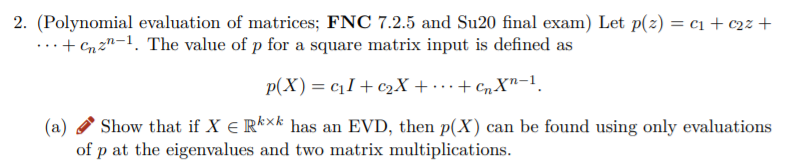

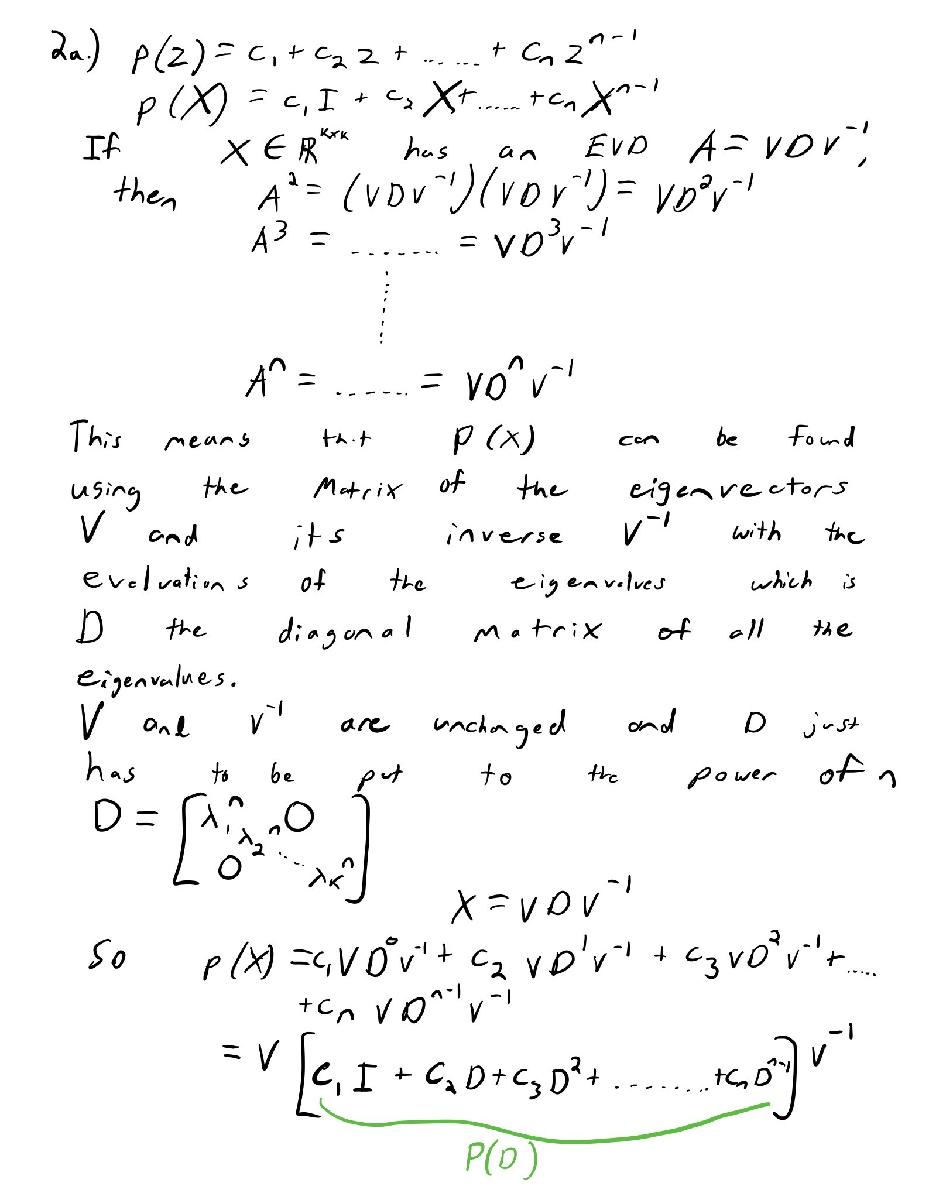

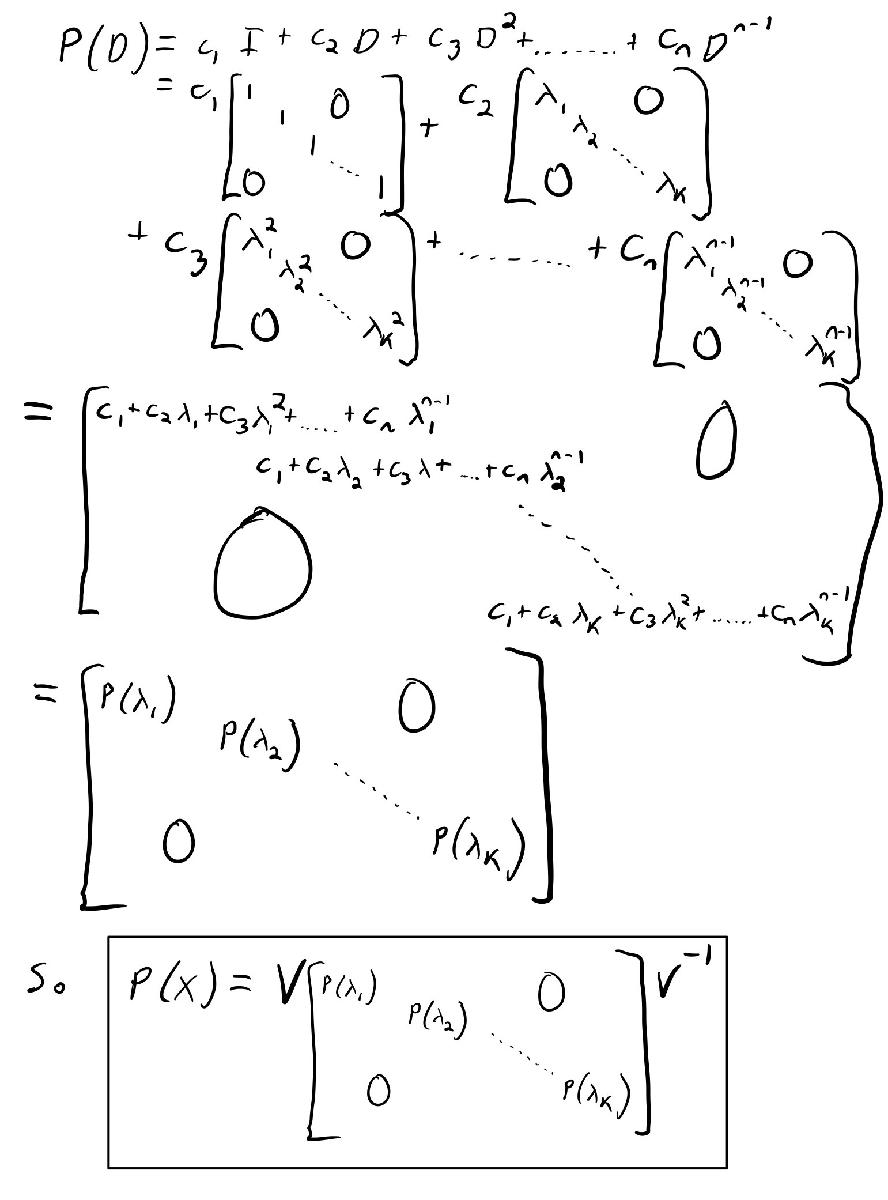

#### Part b.)

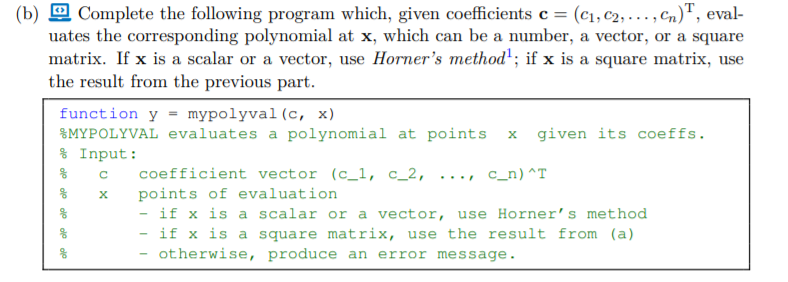

K = [1 2; 3 4]                  %test matrix

K =      1     2
     3     4


c = [2 3 4 5].^2;               %coefficient vector
x = [1 2 3 4 5 6 7];            %test vector
l = 2;                          %test scalar
y = mypolyval(c, K);

ans =      2     1


z = flip(polyvalm(c, K));
p = mypolyval(c, x);
k = flip(polyval(c,x));
n = mypolyval(c, l);
m = polyval(c,l);

## Problem 3. 

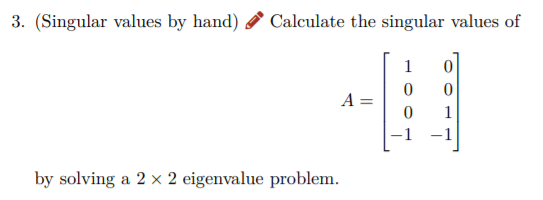

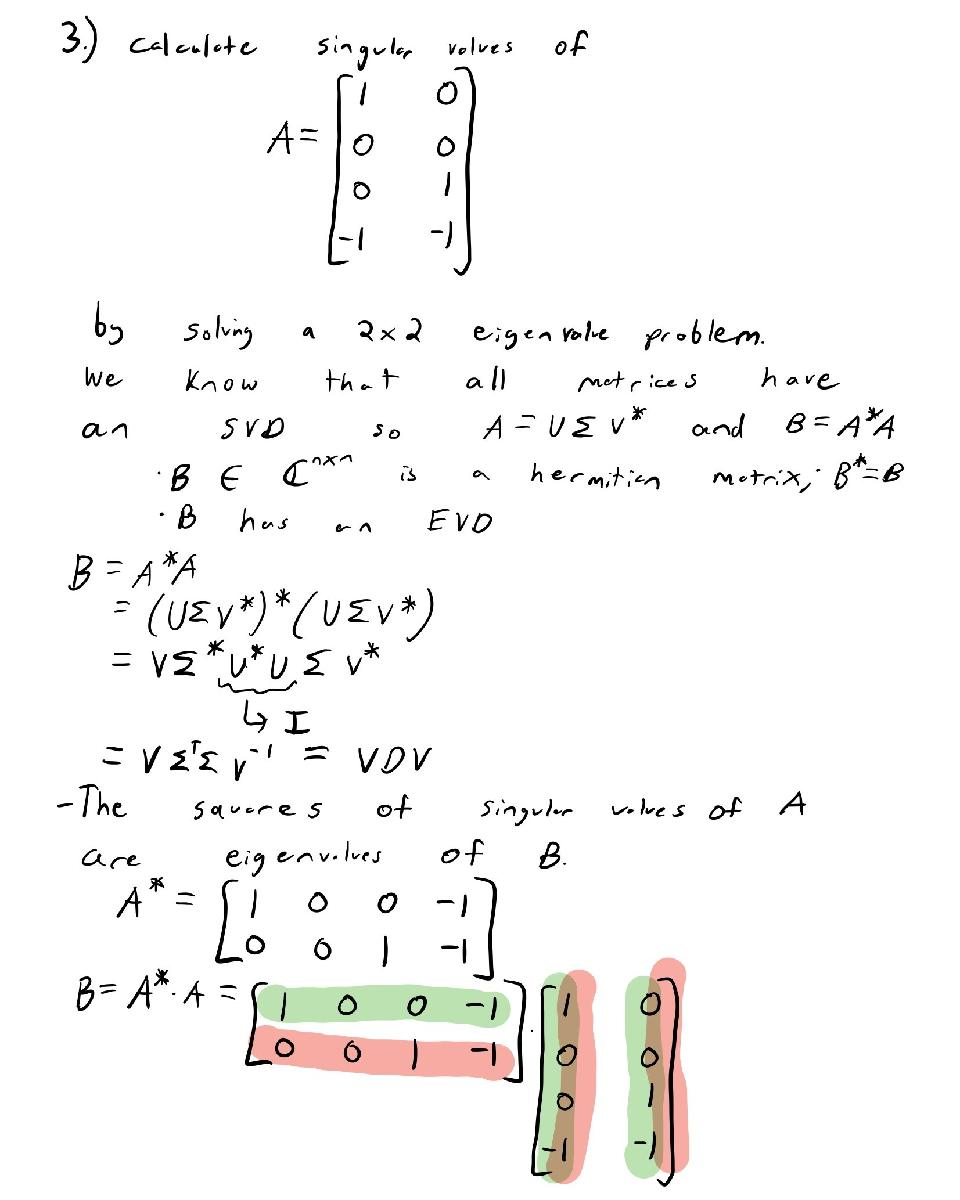

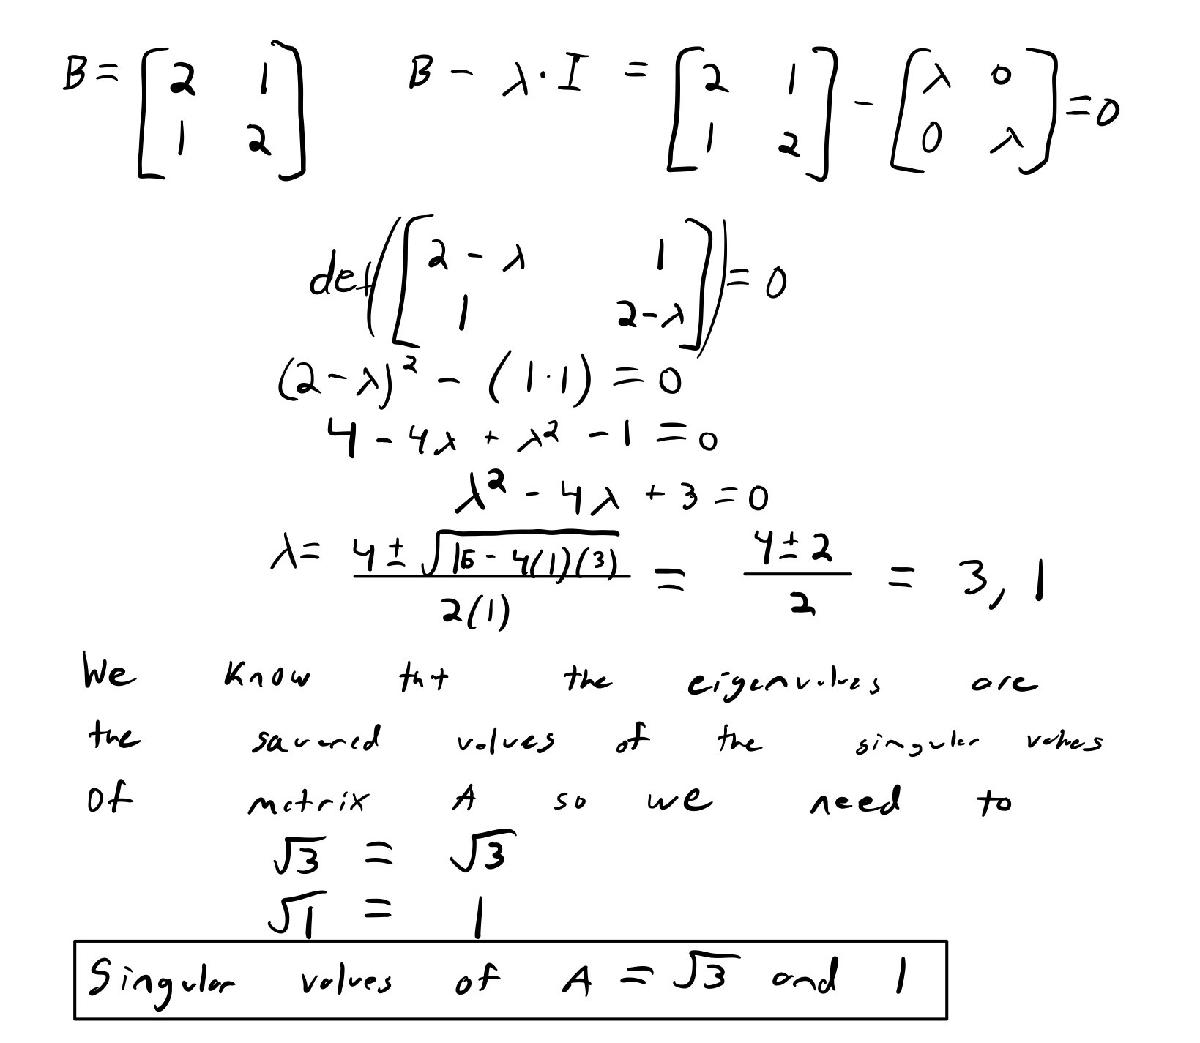

## Problem 4. 

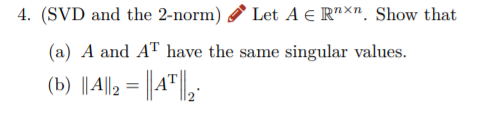

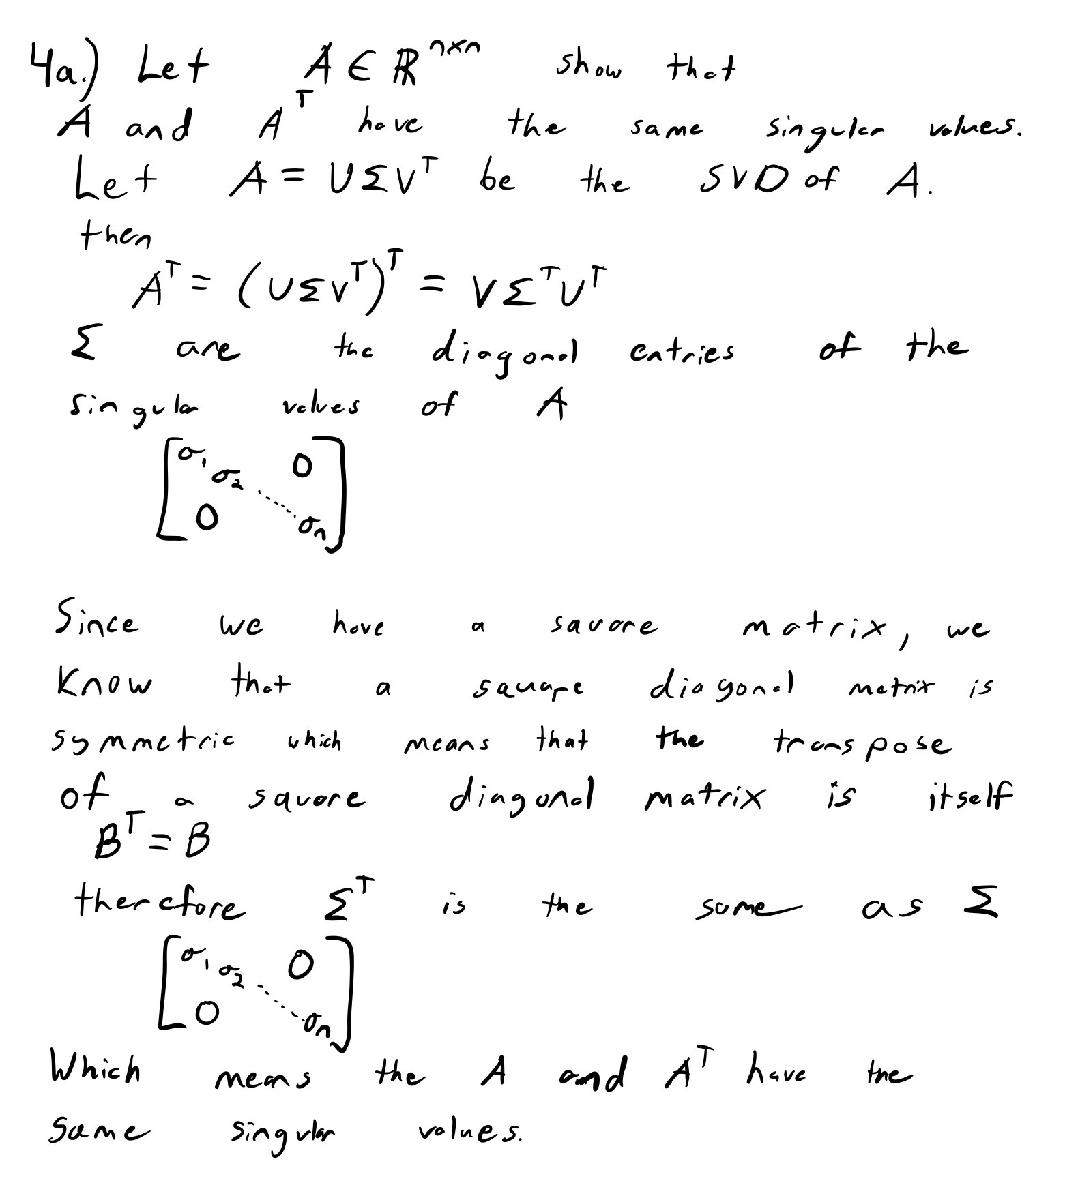

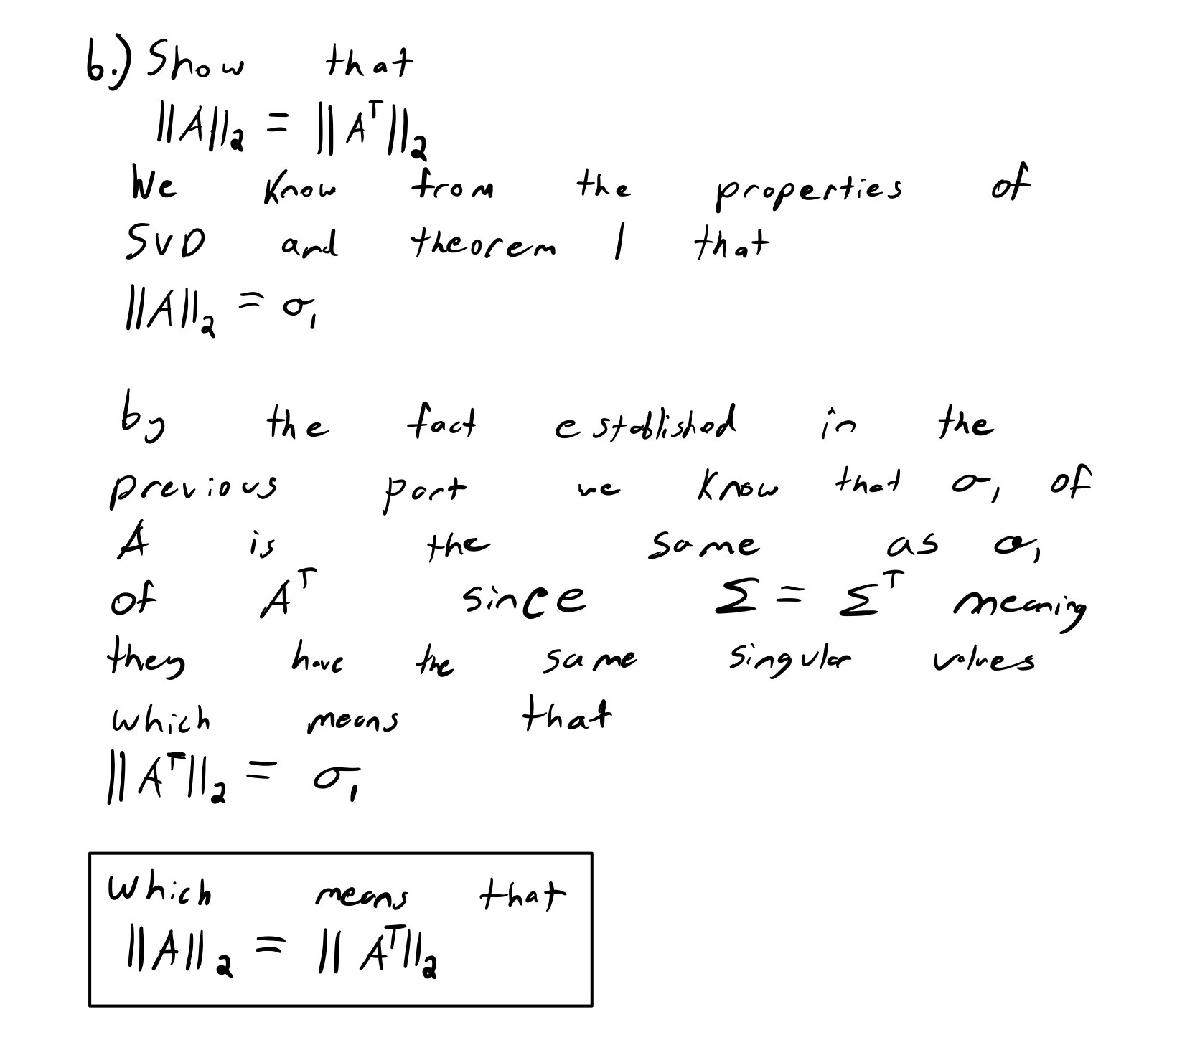

## Problem 5. 

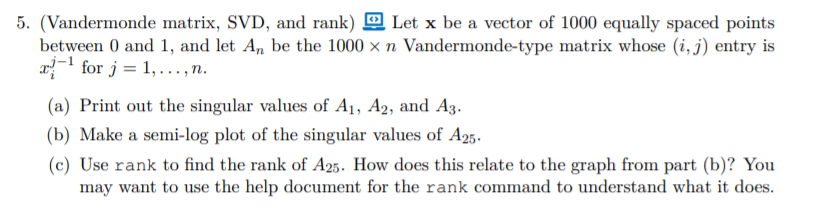

#### Part a.) 

format long g
x = linspace(0, 1, 1000)';
n = 1;
A = x .^ (0:n-1);
s = svd(A)

s =           31.6227766016838


n = 2;
A = x .^ (0:n-1);
s = svd(A)

s =           35.6037782926897
          8.11610362911264


n = 3;
A = x .^ (0:n-1);
s = svd(A)

s =           37.5306448362094
          11.0703713596197
          1.64258230810186


#### Part b.)

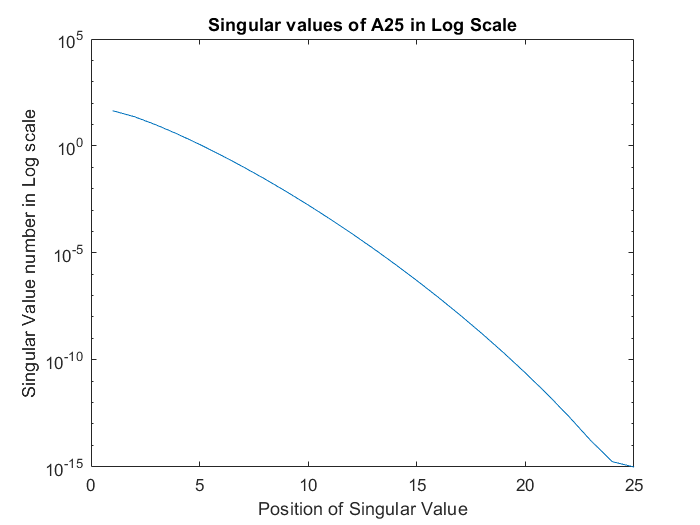

n = 25;
A = x .^ (0:n-1);
s = svd(A);
semilogy(1:25, s)
xlabel('Position of Singular Value')
ylabel('Singular Value number in Log scale')
title('Singular values of A25 in Log Scale')

#### Part c.)

rank(A)

ans =     20


givenTol = max(size(A)) * eps(norm(A))

givenTol =         7.105427357601e-12


As we see used in the documentation of the rank command it is checking to see the number of singular values of A larger than a tolerance which if you don't provide a tolerance, it provides one for you which is the calculation you see above under the variable givenTol. This helps us to understand why rank of A is 20 since if we look at the graph there are values that are below 7.12x10^-12 which means that they are not considered to be within the tolerance that is given in the rank command, which means that some of the values are just considered 0 and since the rank is meant to produce all nonzero singular values since those last few are considered to be 0 then it just thinks that there actually 20 singular values when in reality there are more as you get to much smaller numbers in the vector of all of the singular values. So we see that there can be some error in the rank command if you try to get singular values that are smaller than the given tolerance put into the rank command.

## Function mypolyval

function y = mypolyval(c, x)
%MYPOLYVAL evaluates a polynomial at points x given its coeffs.
% Input:
% c coefficient vector (c_1, c_2, ..., c_n)^T
% x points of evaluation
% - if x is a scalar or a vector, use Horner’s method
% - if x is a square matrix, use the result from (a)
% - otherwise, produce an error message

sizeOfX = size(x);

if sizeOfX(:,1) == 1 || sizeOfX(:,2) == 1
    n = max(size(c));
    for i = 1:max(size(x))
        y(i) = c(n);          % This algorithm is called Horner's rule.
        for j = n-1:-1:1
            y(i) = y(i)*x(i) + c(j);
        end
    end
elseif sizeOfX(:,1) > 1 && sizeOfX(:,2) > 1
    [V, ~] = eig(x);
    lambda = eig(x);
    size(lambda)
    changedLambda = mypolyval(c,lambda);
    y = V * diag(changedLambda) / V;
else
    fprintf('Invalid Syntax for function, please produce a scalar, vector, or matrix')
end
end